% Presetting
PosExtract=[0; 0; 0; 1];

$$T01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & -\sin\left(\theta_{1}\right) & 0 & 0\\ \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T12 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & L_{1}\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T23 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & L_{2}\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T34 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right) & 0 & L_{3}\\ \sin\left(\theta_{4}\right) & \cos\left(\theta_{4}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T4E = \left(\begin{array}{cccc} 1 & 0 & 0 & L_{4}\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T0E = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -\sigma_{2} & 0 & L_{4}\,\sigma_{1}+L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right)+L_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ \sigma_{2} & \sigma_{1} & 0 & L_{4}\,\sigma_{2}+L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\sin\left(\theta_{1}\right)+L_{3}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}\right)\\ \sigma_{2}=\sin\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}\right) \end{array}$$

$$p0E = \left(\begin{array}{c} L_{4}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}\right)+L_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right)+L_{3}\,\cos\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ L_{4}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}+\theta_{4}\right)+L_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\sin\left(\theta_{1}\right)+L_{3}\,\sin\left(\theta_{1}+\theta_{2}+\theta_{3}\right)\\ 0\\ 1 \end{array}\right)$$

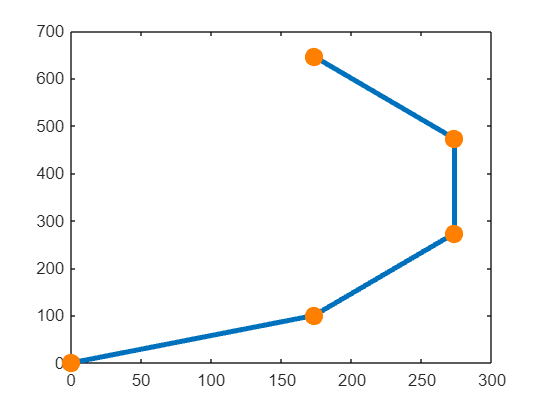

p =   Line - 속성 있음:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 3
             Marker: 'o'
         MarkerSize: 8
    MarkerFaceColor: [1 0.5000 0]
              XData: [0 173.2051 273.2051 273.2051 173.2051]
              YData: [0 100.0000 273.2051 473.2051 646.4102]

  모든 속성 표시


% 4-DoF Manipulator Type1 Inverse Kinematics test by plot graph
EndpointPos = [400;0;0];

% Inverse Kinematics Solving
x = EndpointPos(1);
y = EndpointPos(2);
z = EndpointPos(3);
L1=200;
L2=200;
L3=200;
L4=200;
% Need New Inverse Kinematics Algorithm

% Base to Arm1
a0 = 0;
alpha0 = 0;
d1 = 0;
T01 = DHParameter(a0, alpha0, d1, theta1);

% Arm1 to Arm2
a1 = L1;
alpha1 = 0;
d2 = 0;
T12 = DHParameter(a1, alpha1, d2, theta2);

% Arm2 to Arm3
a2 = L2;
alpha2 = 0;
d3 = 0;
T23 = DHParameter(a2, alpha2, d3, theta3);

% Arm3 to Arm4
a3 = L3;
alpha3 = 0;
d4 = 0;
T34 = DHParameter(a3, alpha3, d4, theta4);

% Arm4 to Endpoint
a4 = L4;
alpha4 = 0;
d5 = 0;
theta5 = 0;
T4E = DHParameter(a4, alpha4, d5, theta5);

% Base to Each Coordinate
T02 = T01*T12;
T03 = T01*T12*T23;
T04 = T01*T12*T23*T34;
T0E = T01*T12*T23*T34*T4E;

% Position of Each Coordinate according to Base Coordinate
p01=T01*PosExtract;
p02=T02*PosExtract;
p03=T03*PosExtract;
p04=T04*PosExtract;
p0E=T0E*PosExtract;

% plot
p = plot([p01(1,1), p02(1,1), p03(1,1), p04(1,1), p0E(1,1)],[p01(2,1), p02(2,1), p03(2,1), p04(2,1), p0E(2,1)],'-o','LineWidth',3);
p.MarkerFaceColor = [1 0.5 0];
p.MarkerSize = 8;
p.MarkerEdgeColor = [1 0.5 0]